%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%                FMCW Radar Simulator               %
%                                                   %
% Author: Lin Junyang                               %
% Email : linjy@163.com                             %
% Date  : 2019-6-15                                 %
%                                                   %
% All Rights Reserved.                              %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% A simulatior of 1 TX antena and 2 RX antena FMCW radar.
% Simulation of close handwave movement: Left - Right

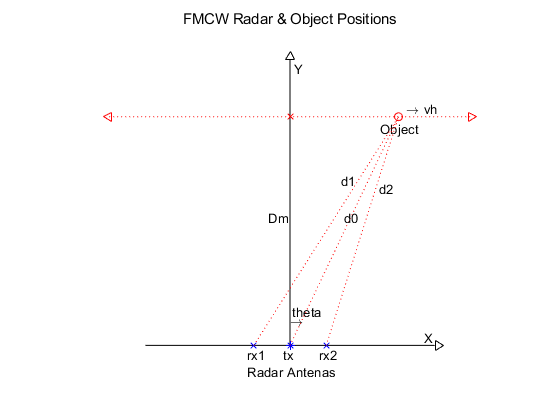

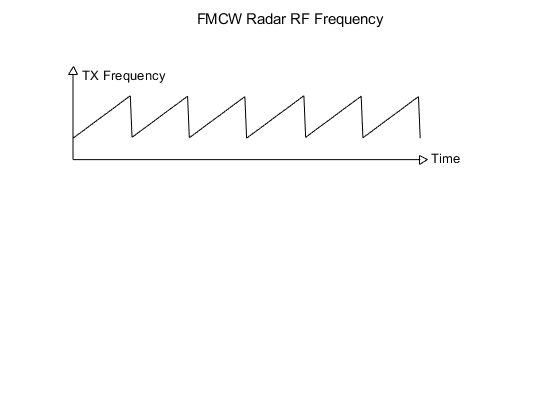

radar_simulation_plot_basis

SimulationTime = 2;                     % simulation time seconds
SampleRate = 2e6;                       % 2MHz radar data sample rate
dt = 1/SampleRate;                      % data point interval
ChirpPeriod = 1e-3;                     % 1ms
ChirpNum = SimulationTime/ChirpPeriod;  % number of chirps
N = SimulationTime*SampleRate;          % data points for simulation
n = 1:N;                                % data points indexes
t = (n-1)*dt;                           % time

Dm = 0.08;              % 8cm, distance vertical
C = 3e8;                % speed of light
S = 4e9/ChirpPeriod;    % radar parameter, 4GHz/ms
Lamda = 0.012;          % radar parameter, 12mm lamda
Dx = 1*(Lamda/2);       % rx1 rx2 distance

x0 = 0;                 % tx position x
y0 = 0;                 % tx position y
x1 = -Dx/2;             % rx1 position x
y1 = 0;                 % rx1 position y
x2 = Dx/2;              % rx2 position x
y2 = 0;                 % rx2 position y

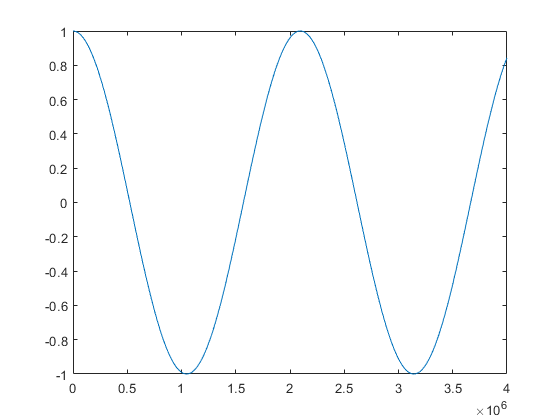

vh = cos(6*t);          % simulation of close handwave movement
figure;plot(vh)

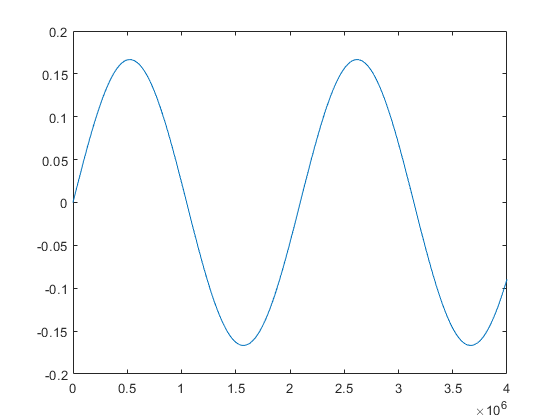

y = Dm;                 % Object horizential distance from radar
x = zeros(1,N);         % Object x postion

x(1) = 0;
for k = 2:N
    x(k) = x(k-1) + vh(k-1)*dt;
end
figure;plot(x)

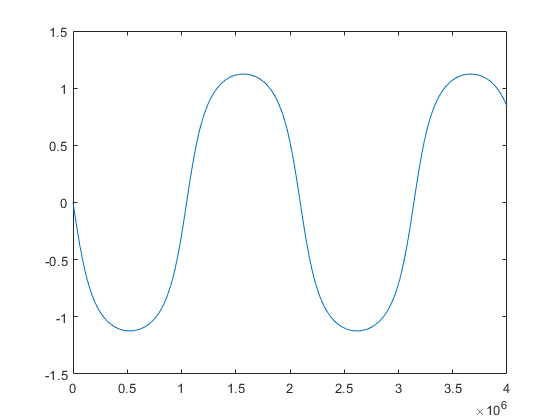

theta = -atan(x/y);
figure;plot(theta)

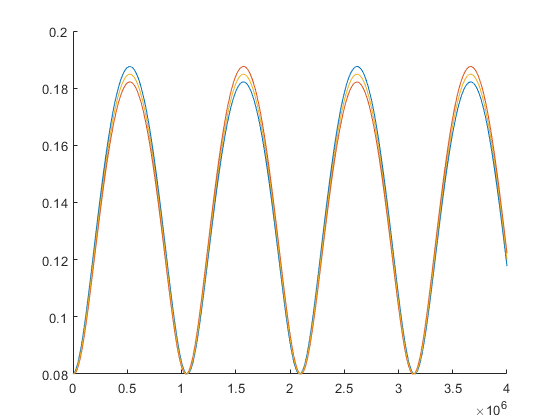

d0 = ((x-x0).^2 + (y-y0).^2).^0.5;
d1 = ((x-x1).^2 + (y-y1).^2).^0.5;
d2 = ((x-x2).^2 + (y-y2).^2).^0.5;
figure;hold on;plot(d1);plot(d2);plot(d0)

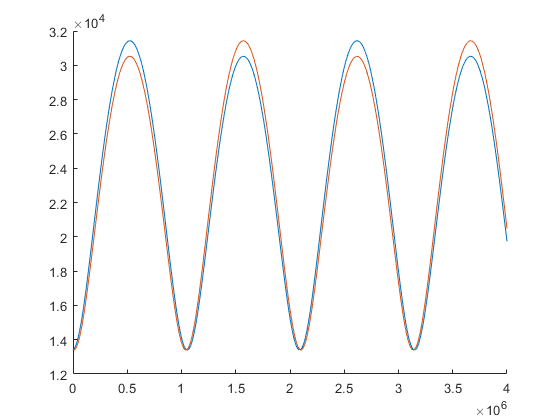

if1 = S*2*d1/C;
if2 = S*2*d2/C;

w1 = 2*pi*if1;
w2 = 2*pi*if2;

figure;hold on;plot(w1);plot(w2);

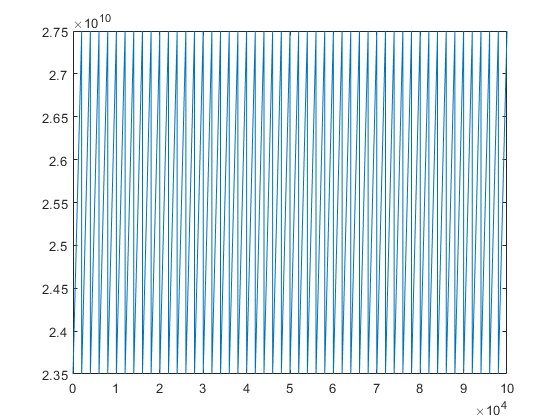

tx_f = 23.5e9 + mod(t,ChirpPeriod)*S;
ChirpDataLen = ChirpPeriod*SampleRate;
figure; plot(tx_f(1:100000))

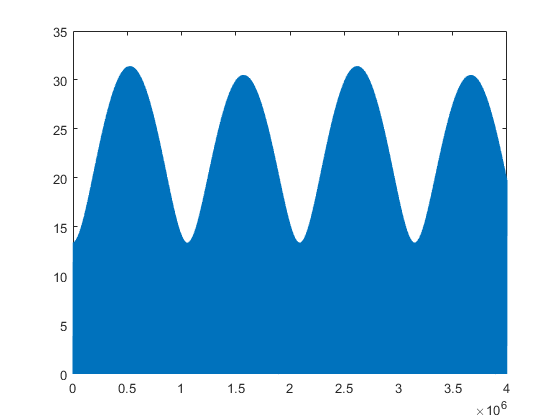

rx1_wt_phi = zeros(1,N);
rx2_wt_phi = zeros(1,N);


for k = 1:N
    if mod(k,ChirpDataLen)==1
        rx1_wt_phi(1) = 0;
        rx2_wt_phi(1) = 0;
    else
        rx1_wt_phi(k) = rx1_wt_phi(k-1)+w1(k-1)*dt;
        rx2_wt_phi(k) = rx2_wt_phi(k-1)+w2(k-1)*dt;
    end
end
figure; plot(rx1_wt_phi)

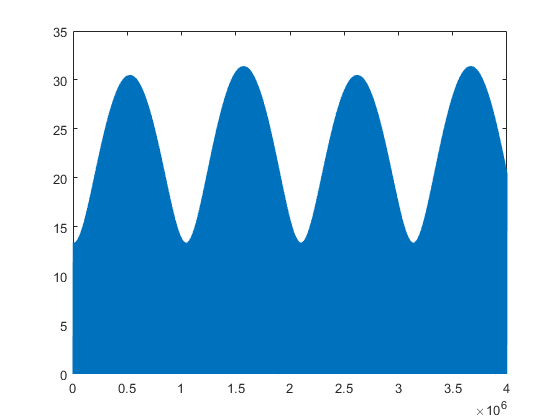

figure; plot(rx2_wt_phi)

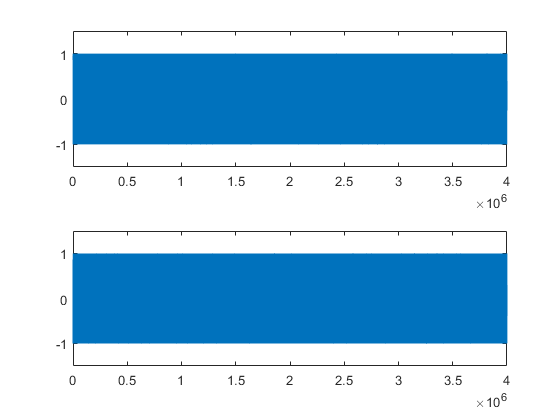

rx1_phi = rx1_wt_phi + (d0+d1)*2*pi/Lamda;
rx2_phi = rx2_wt_phi + (d0+d2)*2*pi/Lamda;

rx1 = sin(rx1_phi) + cos(rx1_phi)*1j;
rx2 = sin(rx2_phi) + cos(rx2_phi)*1j;

figure;
subplot(2,1,1)
plot(real(rx1));ylim([-1.5 1.5])
subplot(2,1,2)
plot(real(rx2));ylim([-1.5 1.5])

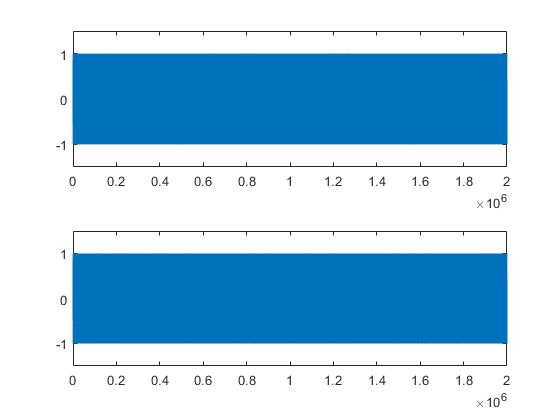


figure;
subplot(2,1,1)
plot(real(rx1(1:2e6)));ylim([-1.5 1.5])
subplot(2,1,2)
plot(real(rx2(1:2e6)));ylim([-1.5 1.5])

% Add random noise
NoiseAmp = 0.07;
RX1_I = real(rx1 + rand(size(rx1))*NoiseAmp + rand(size(rx1))*NoiseAmp*1j);
RX1_Q = imag(rx1 + rand(size(rx1))*NoiseAmp + rand(size(rx1))*NoiseAmp*1j);
RX2_I = real(rx2 + rand(size(rx2))*NoiseAmp + rand(size(rx2))*NoiseAmp*1j);
RX2_Q = imag(rx2 + rand(size(rx2))*NoiseAmp + rand(size(rx2))*NoiseAmp*1j);

RX1_CHIRPS_I = zeros(ChirpNum,ChirpDataLen);
RX1_CHIRPS_Q = zeros(ChirpNum,ChirpDataLen);
RX2_CHIRPS_I = zeros(ChirpNum,ChirpDataLen);
RX2_CHIRPS_Q = zeros(ChirpNum,ChirpDataLen);

for k = 1:ChirpNum
    chirp_start = (k-1)*ChirpDataLen + 1;
    chirp_end = k*ChirpDataLen;
    RX1_CHIRPS_I(k,:) = RX1_I(chirp_start:chirp_end);
    RX1_CHIRPS_Q(k,:) = RX1_Q(chirp_start:chirp_end);
    RX2_CHIRPS_I(k,:) = RX2_I(chirp_start:chirp_end);
    RX2_CHIRPS_Q(k,:) = RX2_Q(chirp_start:chirp_end);
    
    % Radar chip TX amplitude modulation
    for m=1:ChirpDataLen
        RX1_CHIRPS_I(k,m) = RX1_CHIRPS_I(k,m)*(m/ChirpDataLen)^0.7;
        RX1_CHIRPS_Q(k,m) = RX1_CHIRPS_Q(k,m)*(m/ChirpDataLen)^0.7;
        RX2_CHIRPS_I(k,m) = RX2_CHIRPS_I(k,m)*(m/ChirpDataLen)^0.7;
        RX2_CHIRPS_Q(k,m) = RX2_CHIRPS_Q(k,m)*(m/ChirpDataLen)^0.7;
    end
end

RX1_CHIRPS_I = RX1_CHIRPS_I(:,1:1360);
RX1_CHIRPS_Q = RX1_CHIRPS_Q(:,1:1360);
RX2_CHIRPS_I = RX2_CHIRPS_I(:,1:1360);
RX2_CHIRPS_Q = RX2_CHIRPS_Q(:,1:1360);

chirp_sample_idx = randi(ChirpNum);

chirp_sample_idx = 1173

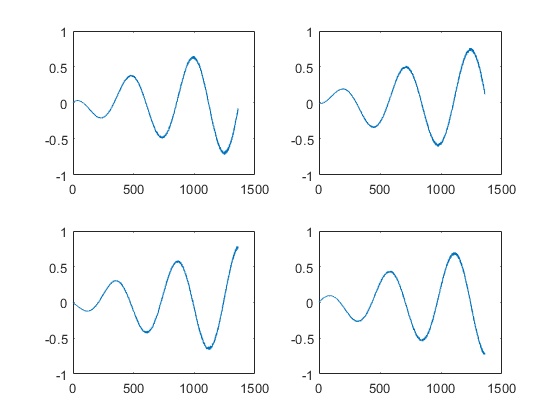

figure; 
title(['Chirp sample index: ',num2str(chirp_sample_idx)])
subplot(2,2,1);plot(RX1_CHIRPS_I(chirp_sample_idx,:))
subplot(2,2,2);plot(RX2_CHIRPS_I(chirp_sample_idx,:))
subplot(2,2,3);plot(RX1_CHIRPS_Q(chirp_sample_idx,:))
subplot(2,2,4);plot(RX2_CHIRPS_Q(chirp_sample_idx,:))

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% FMCW Radar Simulation Outputs are:                %
%       RX1_CHIRPS_I                                %
%       RX1_CHIRPS_Q                                %
%       RX2_CHIRPS_I                                %
%       RX2_CHIRPS_Q                                %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%